2. Reprezentati grafic polinoamele fundamentale cand se dau gradul si nodurile. 

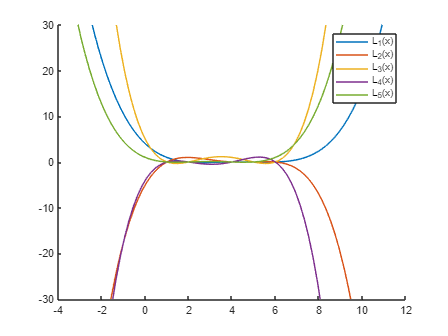

nodes = [1,2,4,5,6];
m=size(nodes,2);

hold on
x = linspace(mean(nodes)-10,mean(nodes)+10,100);
for k=1:m
    plot(x, polyval(L(nodes,k),x),"DisplayName",sprintf("L_{%i}(x)",k))           
end
legend
ylim([-30 30])
hold off

Functie care returneaza fundamental $L_k(x) = \prod_{j=1, j\neq k}^m \frac{x-x_j}{x_k-x_j}$, unde $x_1, \ldots, x_n$ sunt noduri.

function lk = L(nodes,k)
    % polinomul fundamental L_k pentru nodurile nodes_1,...,nodes_n       
    % lk = prod_{j,j!=k}(x-xj)/prod_{j,j!=k}(xk-xj)
    m = size(nodes,2);
    roots = cat(2, nodes(1:k-1), nodes(k+1:m));    
    p = poly(roots);
    lk = p ./ polyval(p,nodes(k));
end